# Fahrplansimulation Sonntag

% V5.0 für Sonntag

Import_timetableSunday;  % Fahrplan wird eingelesen

TimetableSunday = 75×8 table
    Abfahrt    Ankunft      Zeit       Start    Verbindung    Gleis    Strecke    Fahrzeugtyp
    _______    _______    _________    _____    __________    _____    _______    ___________

    0.32986    0.33194    0.0020833    28500       S6         43/44     HB_ZH         ""     
    0.33056    0.33333    0.0027778    28560       S11        43/44     HB_ZH         ""     
    0.33125    0.33264    0.0013889    28620       S6         41/42     ST_ZH         ""     
    0.33194    0.33333    0.0013889    28680       S9         43/44     ZH_ST         ""     
    0.33264    0.33472    0.0020833    28740       S9         41/42     ST_ZH         ""     
    0.33264    0.33403    0.0013889    2

Streckenparameter2;  % Strecken- und Fahrzeugparameter werden eingelesen
% Streckenparameter_parsing;

% StartToEnd = zeros(length(TimetableSunday.Start),3);
Fz_Nr = 1; % Initialisierung der Fahrzeugnummer

% erstellen einer Matrix, in welcher die Daten gespeichert werden.
sim_data = zeros(864000, length(TimetableSunday.Start)+1);
sim_data(:,1) = 0.1:0.1:86400;

FZ = RE450; % Bestimmung des Fahrzeugtyps
% Str = ZH_HB; % Bestimmung der befahrenen Strecke
% Str = CH_StGallen_Wil;

% loop über den gesamten Tag --> alle Fahrten auf den definierten Strecken
% werden simuliert
for t = 28500:32520 

    for i = 1:length(TimetableSunday.Start)

        if (t == TimetableSunday.Start(i))
            disp(TimetableSunday.Start(i))
            
            % Bestimmung der Strecke laut Fahrplan
            Str = Strecken.(string(TimetableSunday.Strecke(i)));
            % Bestimmung des Fahrzeugtyps laut Fahrplan
%             FZ = TimetableSunday.Fahrzeugtyp(i);

            % Aufruf der Funktion für die Simulation der Zugfahrt
            [Str_sim, Fz_sim, CompData] = Fahrtsimulation6(Str, FZ, const);

            % aktueller Zeitpunkt festellen
            pos = find(sim_data(:, 1) == t);

            % Daten zum richtigen Zeitpunkt in die Matrix schreiben
            sim_data(pos:pos + length(Str_sim.Strecke) - 1, Fz_Nr + 1) = Fz_sim.Leistung;
            % Es kann angegeben werden, welcher Parameter ausgelesen werden
            % soll.

            % Zeitpunkt an welchem Fahrzeug losfährt und ankommt
            time = seconds(transpose((t):0.1:(t-0.1+length(Str_sim.Strecke)/10)));
            time.Format = 'hh:mm:ss.S';
            CompData.time = time;
            Fz_Nr = Fz_Nr + 1;   % nächstes Fahrzeug
            StrName = "Fahrzeug" + i; % Name für Fahrzeug in Datenstruktur
            CompleteData.(StrName) = CompData; % Simulierte Daten werden in Strucktur gespeichert

        end

    end

end

       28500

       28560

       28620

       28680

       28740

       28740

       28800

       28800

       28860

       28920

       29040

       29100

       29220

       29220

       29340

       29340

       29340

       29400

       29460

       29460

       29460

       29640

       29700

       29700

       29760

       29760

       29820

       29880

       29940

       29940

       30120

       30120

       30240

       30300

       30360

       30420

       30480

       30540

       30540

       30600

       30660

       30720

       30840

       30900

       31020

       31020

       31140

       31140

       31140

       31200

       31260

       31260

       31260

       31440

       31500

       31500

       31560

       31560

       31620

       31680

       31740

       31740

       31920

       31920

       32040

       32100

       32100

       32160

       32220

       32280

       32340

      


P_tot = sum(sim_data(:,2:end),2); % Gesamte Leistung aller Strecken wird berechnet





## Analyse der Leistung

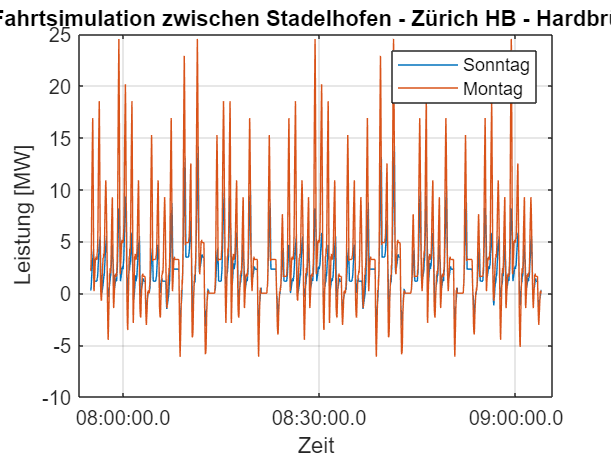

start = find((sim_data(1:end,2)),1,'first');

finish = find((sim_data(1:end,Fz_Nr)),1,'last');
% finish = start + length(Str_sim.Strecke)-1;
active = sim_data(start:finish, 1:end);
% 
time = seconds((active(1:end,1)));
time.Format = 'hh:mm:ss.S';
plot(time, P_tot(start:finish,1)/1000, time, P_totMonday(start:finish,1)/1000)
%plot(time, P_totMondayNew(start:finish,1)/1000, time, P_totMondayOld(start:finish,1)/1000)
grid()
title('Vergleich Leistung der Fahrtsimulation zwischen Stadelhofen - Zürich HB - Hardbrücke Montag und Sonntag')
xlabel('Zeit')
ylabel('Leistung [MW]')
legend(["Sonntag" "Montag"])


% % 
% plot(time, active.Strecke)
% plot(time,P_tot(start:finish), time, sim_ZHHB(2,start:finish), time, sim_ZHHB(3, start:finish), time, sim_ZHHB(4, start:finish), time, sim_ZHHB(5, start:finish))
% grid()
% 
% 
% 
% for i = 2:Fz_Nr-1
%     plot(time, sim_ZHHB(i, start:finish)); hold on
% end


## Plotten

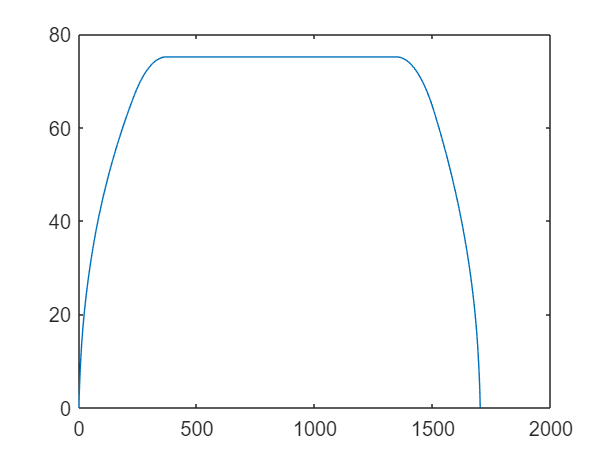

plot(Str_sim.Strecke, Fz_sim.Geschwindigkeit)

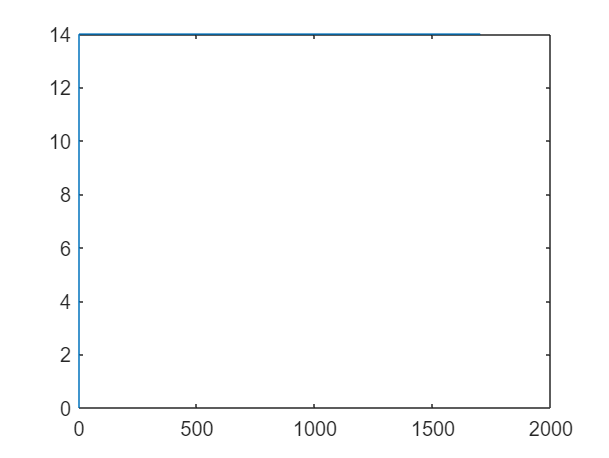



plot(Str_sim.Strecke, Str_sim.Steigung)

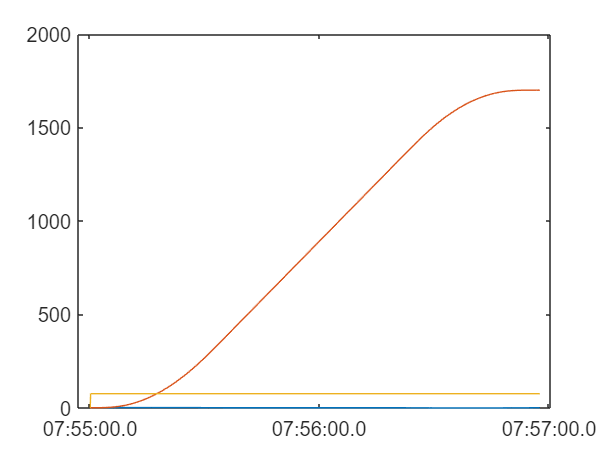



% plot(sim_data.Zeit,sim_data.Geschwindigkeit)


plot(time(1:length(Str_sim.Strecke)), Fz_sim.Beschleunigung, time(1:length(Str_sim.Strecke)), Str_sim.Strecke, time(1:length(Str_sim.Strecke)), Str_sim.("MaximalGeschw."))

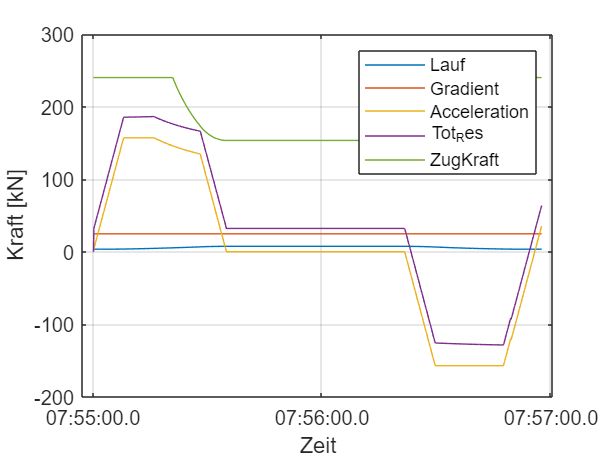


plot(time(1:length(Str_sim.Strecke)), Fz_sim.Laufwiderstand, time(1:length(Str_sim.Strecke)), Fz_sim.Steigungswiderstand, time(1:length(Str_sim.Strecke)), Fz_sim.Beschleunigungswiderstand, time(1:length(Str_sim.Strecke)), Fz_sim.Gesamtwiderstand, time(1:length(Str_sim.Strecke)), Fz_sim.Zugkraft)
xlabel('Zeit')
ylabel('Kraft [kN]')
grid()
legend(["Lauf" "Gradient" "Acceleration" "Tot_Res" "ZugKraft"])

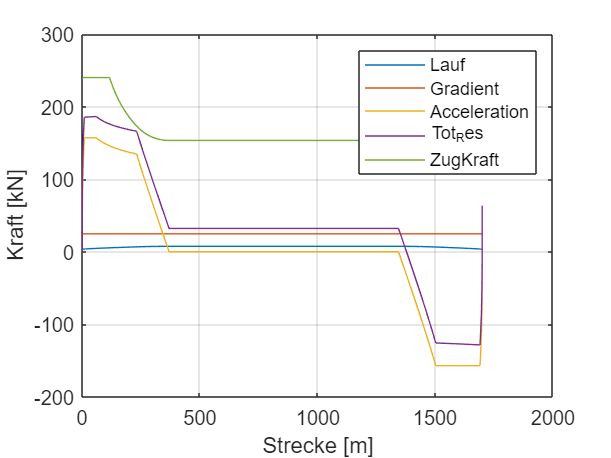


plot(Str_sim.Strecke, Fz_sim.Laufwiderstand, Str_sim.Strecke, Fz_sim.Steigungswiderstand, Str_sim.Strecke, Fz_sim.Beschleunigungswiderstand, Str_sim.Strecke, Fz_sim.Gesamtwiderstand, Str_sim.Strecke, Fz_sim.Zugkraft)
xlabel('Strecke [m]')
ylabel('Kraft [kN]')
grid()
legend(["Lauf" "Gradient" "Acceleration" "Tot_Res" "ZugKraft"])

## Plotten einer einzelnen Fahrt

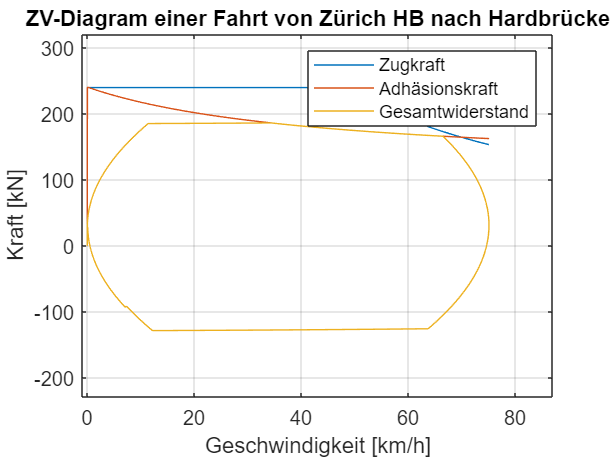

% Fahrt 2 von Zürich nach Hardbrücke:

% plot(CompleteData.Fahrzeug2.time, CompleteData.Fahrzeug2.Strecke)

plot(CompleteData.Fahrzeug2.Geschwindigkeit, CompleteData.Fahrzeug2.Zugkraft, CompleteData.Fahrzeug2.Geschwindigkeit, CompleteData.Fahrzeug2.("Adhäsionskraft"), CompleteData.Fahrzeug2.Geschwindigkeit,CompleteData.Fahrzeug2.Gesamtwiderstand)
grid()
xlabel('Geschwindigkeit [km/h]')
ylabel('Kraft [kN]')
legend(["Zugkraft" "Adhäsionskraft" "Gesamtwiderstand"])
title("ZV-Diagram einer Fahrt von Zürich HB nach Hardbrücke")

## Vergleich Sonntag mit Wochentag

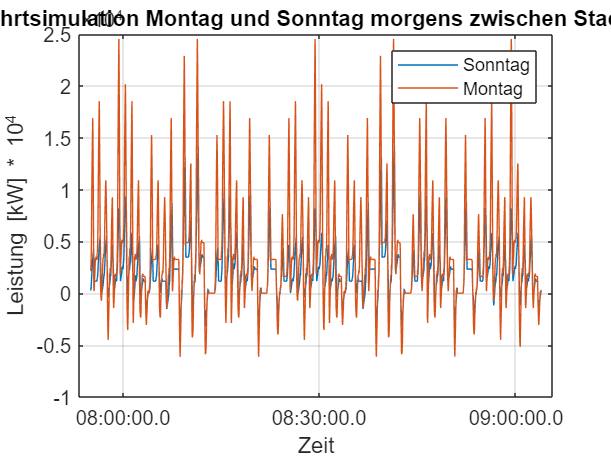

%plot(time,P_tot(start:finish), time, P_totMonday(start:finish))

plot(time,P_tot(start:finish), time, P_totMonday(start:finish))
grid()
title('Vergleich der Leistungen der Fahrtsimulation Montag und Sonntag morgens zwischen Stadelhofen - Zürich HB - Hardbrücke')
xlabel('Zeit')
ylabel('Leistung [kW] * 10^4')
legend(["Sonntag" "Montag"])

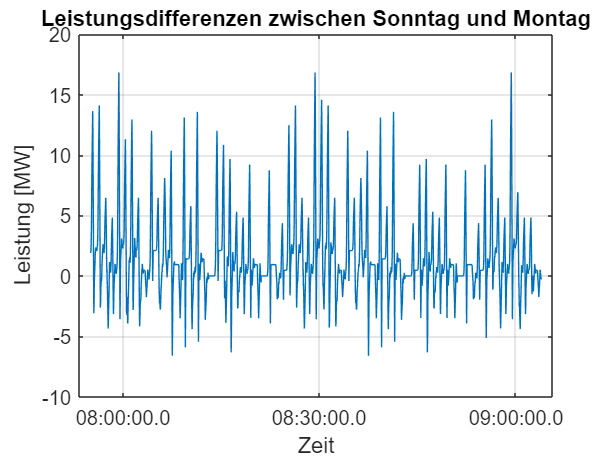


P_diff = P_totMonday - P_tot;
plot(time, P_diff(start:finish)/1000)
grid()
title('Leistungsdifferenzen zwischen Sonntag und Montag')
xlabel('Zeit')
ylabel('Leistung [MW]')

## 8 minütiger Mittelwert der Leistung

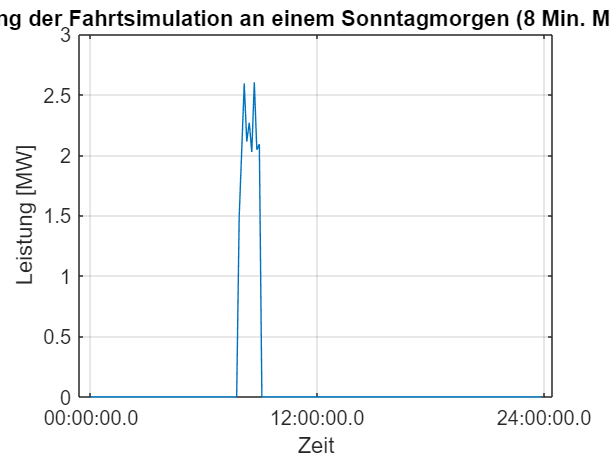


P_tot8Min = mean(reshape(P_tot,4800,[]))';
P_tot8Min(1,2) = 0;

for i = 2:180
    P_tot8Min(i, 2) = P_tot8Min(i-1,2) + 480;
end

time = seconds(P_tot8Min(:,2));
time.Format = 'hh:mm:ss.S';


P_tot8MinSunday = P_tot8Min;
plot(time, P_tot8MinSunday(:,1)/1000)
grid()
title('Leistung der Fahrtsimulation an einem Sonntagmorgen (8 Min. Mittelwert)')
xlabel('Zeit')
ylabel('Leistung [MW]')

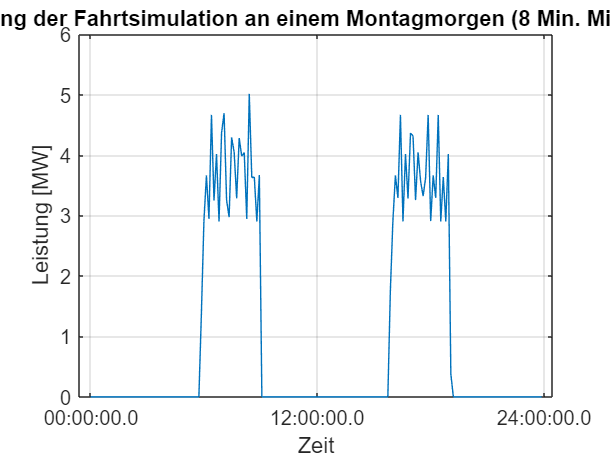


plot(time, P_tot8MinMonday(:,1)/1000)
grid()
title('Leistung der Fahrtsimulation an einem Montagmorgen (8 Min. Mittelwert)')
xlabel('Zeit')
ylabel('Leistung [MW]')

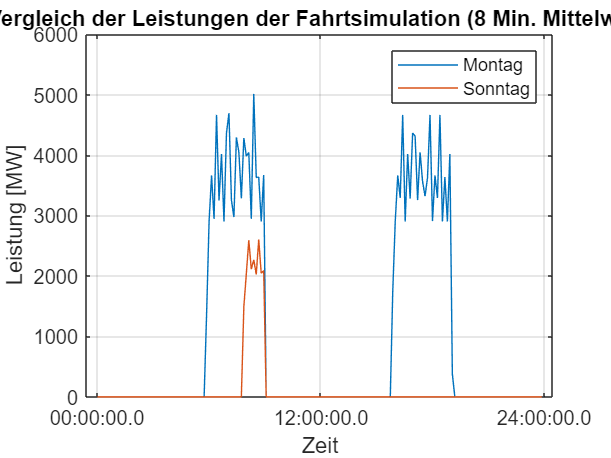



plot(time, P_tot8MinMonday(:,1), time, P_tot8MinSunday(:,1))
grid()
title('Vergleich der Leistungen der Fahrtsimulation (8 Min. Mittelwert)')
xlabel('Zeit')
ylabel('Leistung [MW]')
legend(["Montag" "Sonntag"])

## 8 Min Mittelwert alle 5 Minuten


P_totPos = abs(P_tot);


n = 1;
for i = 1:3000:864000
    if (i <= 4800)
        
        P_tot8MinPos(1:4800,n)  = 0;
       
    else
        for k = 1:4800
            P_tot8MinPos(k ,n) = P_totPos(i-k);
        end
    end
    n = n + 1;
end

P_5to8MinMean = mean(P_tot8MinPos)';

P_5to8MinMean(:,2) = (1:length(P_5to8MinMean)) * 5;

time2 = minutes(P_5to8MinMean(:,2));
time2.Format = 'hh:mm:ss.S';

## Variablen für Sonntag:

P_5to8MinMeanSunday = P_5to8MinMean; % P_5to8MinMean = alle 5 Min. 8 Minuten rückwärts
P_totSunday = P_tot;
P_tot8MinSunday = P_tot8Min;
P_tot8MinPosSunday = P_tot8MinPos;
P_totPosSunday = P_totPos;


## plot Vergleich verschiedener 8 Min Werte

Import_measurements;
plot(time2, P_5to8MinMeanMonday(:,1)/1000, time2, P_5to8MinMeanSunday(:,1)/1000, time2, MeasMonday.P8minMittelMW(2:end))
grid() % 
title('Vergleich 8 Min Mittelwerte mit Messwerten (Sonntag: RE450, Montag: KISS)')
legend(["Montag" "Sonntag" "Messwerte Montag" "Messwerte Sonntag"])

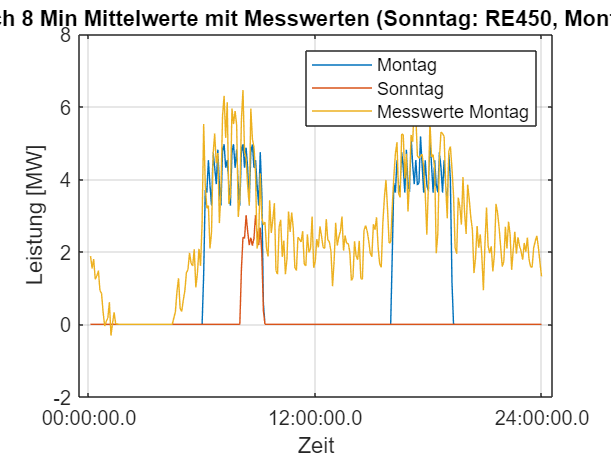

xlabel('Zeit')
ylabel('Leistung [MW]')